
%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = TxNodesOnStreetS10'; %[str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';
%DEN=2059s,22330s,22113s,23916s





ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4)>delta_t*9
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end
    
     
                
  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     11    12    11    10     9     9    10    10     9     9     9     9     8     8     9     9     8     8     9     9
     2     3     3     3     3     3     3     3     3     3     3     2     2     2     1     1     1     1     1     1
    22    22    22    22    22    22    22    22    22    22    22    22    23    23    23    23    23    23    23    23
    12    14    14    15    15    15    14    14    14    14    15    16    16    16    15    15    15    14    13    13


sum(ind2)

ans =     47    51    50    50    49    49    49    49    48    48    49    49    49    49    48    48    47    46    46    46



mean(sum(ind2))

ans = 48.3500

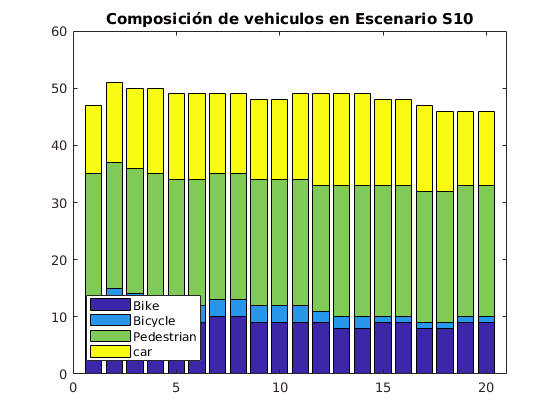



figure (2)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     11    12    11    10     9     9    10    10     9     9     9     9     8     8     9     9     8     8     9     9
     2     3     3     3     3     3     3     3     3     3     3     2     2     2     1     1     1     1     1     1
    22    22    22    22    22    22    22    22    22    22    22    22    23    23    23    23    23    23    23    23
    12    14    14    15    15    15    14    14    14    14    15    16    16    16    15    15    15    14    13    13


sum(ind3)

ans =     47    51    50    50    49    49    49    49    48    48    49    49    49    49    48    48    47    46    46    46



mean(sum(ind3))

ans = 48.3500

ind3./ind2

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



figure (3)
bar(ind3','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


LD_Nodes = TxNodesMovinPedS10'; %[str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';
%DEN=2059s,22330s,22113s,23916s


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4)>delta_t*9
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end
    
     
                
  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     11    12    11    10     9     9    10    10     9     9     9     9     8     8     9     9     8     8     9     9
     2     3     3     3     3     3     3     3     3     3     3     2     2     2     1     1     1     1     1     1
    22    22    22    22    22    22    22    22    22    22    22    22    23    23    23    23    23    23    23    23
    12    14    14    15    15    15    14    14    14    14    15    16    16    16    15    15    15    14    13    13


sum(ind2)

ans =     47    51    50    50    49    49    49    49    48    48    49    49    49    49    48    48    47    46    46    46



mean(sum(ind2))

ans = 48.3500



figure (4)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     10    11    10     9     8     8     9     9     8     8     8     8     7     7     8     8     7     7     8     8
     2     3     3     3     3     3     3     3     3     3     3     2     2     2     1     1     1     1     1     1
    20    20    20    20    20    20    20    20    20    20    20    20    21    21    21    21    21    21    21    21
    12    14    14    15    15    15    14    14    14    14    15    16    16    16    15    15    15    14    13    13


sum(ind3)

ans =     44    48    47    47    46    46    46    46    45    45    46    46    46    46    45    45    44    43    43    43



mean(sum(ind3))

ans = 45.3500

ind3./ind2

ans =     0.9091    0.9167    0.9091    0.9000    0.8889    0.8889    0.9000    0.9000    0.8889    0.8889    0.8889    0.8889    0.8750    0.8750    0.8889    0.8889    0.8750    0.8750    0.8889    0.8889
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9091    0.9091    0.9091    0.9091    0.9091    0.9091    0.9091    0.9091    0.9091    0.9091    0.9091    0.9091    0.9130    0.9130    0.9130    0.9130    0.9130    0.9130    0.9130    0.9130
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


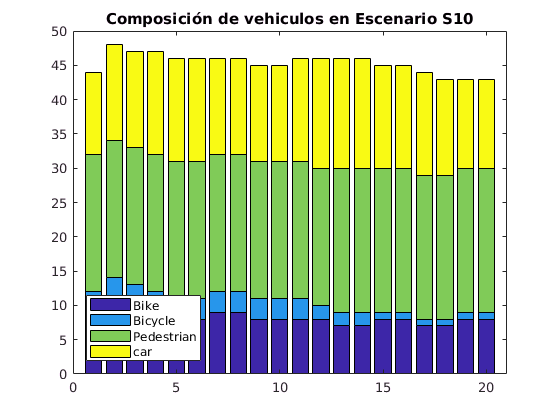


figure (5)
bar(ind3','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])

LD_Nodes = TxNodesBLObstacleS10'; %[str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';
%DEN=2059s,22330s,22113s,23916s





ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4)>delta_t*9
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end
    
     
                
  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     11    12    11    10     9     9    10    10     9     9     9     9     8     8     9     9     8     8     9     9
     2     3     3     3     3     3     3     3     3     3     3     2     2     2     1     1     1     1     1     1
    22    22    22    22    22    22    22    22    22    22    22    22    23    23    23    23    23    23    23    23
    12    14    14    15    15    15    14    14    14    14    15    16    16    16    15    15    15    14    13    13


sum(ind2)

ans =     47    51    50    50    49    49    49    49    48    48    49    49    49    49    48    48    47    46    46    46



mean(sum(ind2))

ans = 48.3500



figure (6)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     11    12    11    10     9     9    10    10     9     9     9     9     8     8     9     9     8     8     9     9
     2     3     3     3     3     3     3     3     3     3     3     2     2     2     1     1     1     1     1     1
    22    22    22    22    22    22    22    22    22    22    22    22    23    23    23    23    23    23    23    23
    12    14    14    15    15    15    14    14    14    14    15    16    16    16    15    15    15    14    13    13


sum(ind3)

ans =     47    51    50    50    49    49    49    49    48    48    49    49    49    49    48    48    47    46    46    46



mean(sum(ind3))

ans = 48.3500

ind3./ind2

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



figure (7)
bar(ind3','stacked')
title('Composición de vehiculos en Escenario S10')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])